In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

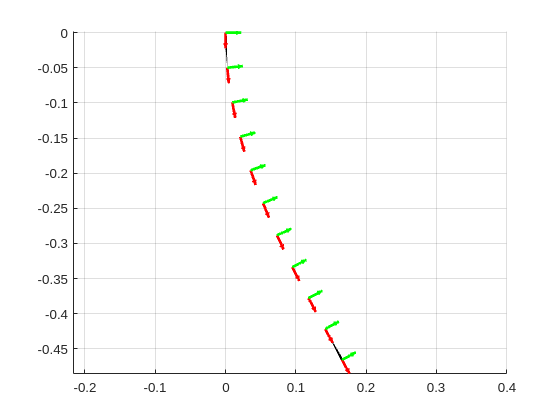

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
q = calc_external_wrench(segment_twists, Q_tip, g_0);

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

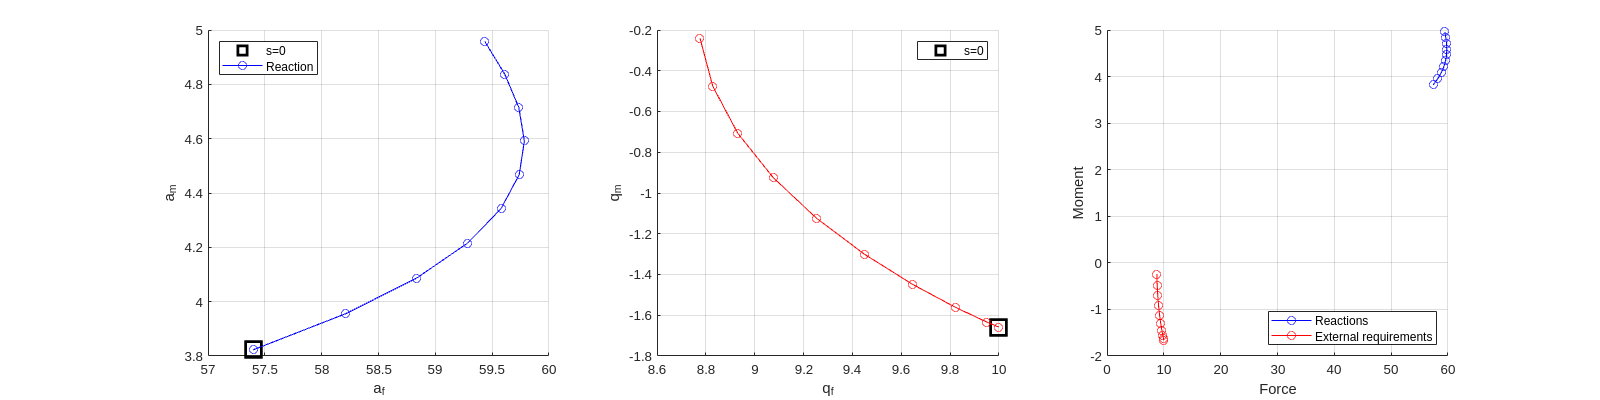

p = [15; 0; 15; 0]; %kPa
reaction_forces = calc_reaction_wrench(segment_twists, p, struct_design);

% Now we plot the two against each other
figure("position", [0, 0, 1600, 400])
subplot(1, 3, 1)
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0", "Reaction", location="Northwest")
xlabel("a_f")
ylabel("a_m")
grid on

subplot(1, 3, 2)
hold on
plot(q(1, 1), q(3, 1), "ksquare", "markersize", 15, "linewidth", 3);
plot(q(1, :), q(3, :), 'r-o');
xlabel("q_f")
ylabel("q_m")
legend("s=0")
grid on

subplot(1, 3, 3)
hold on
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o");
plot(q(1, :), q(3, :), "r-o");
xlabel("Force")
ylabel("Moment")
legend("Reactions", "External requirements", location="southeast")
grid on

The crucial questions for extending our previous work to the variable curvature arm are:

- What will happen to this plot when we traverse the pressure contour? 

- How can we read "designability" from the variable curvature arm's pressure contour?

Now let's try doing this for a whole range of pressures along the pressure contour

N_edge = 25;
t = linspace(0, 4, 4*N_edge);
ps = outline_pressure_space([2, 1, 1, 2], [1, 2, 1, 2], N_edge);
figure()
hold on
plot(t, ps(1, :), "b-", "linewidth", 2);
plot(t, ps(2, :), "r--", "linewidth", 2);
plot(t, ps(3, :), "b--", "linewidth", 2);
plot(t, ps(4, :), 'r-', "linewidth", 2);
set(gcf, "visible", true)
legend("Bellow", "Muscle", "Muscle", "Bellow")

mat_3d_rxns = zeros([size(reaction_forces), length(t)]);
for i = 1 : size(ps, 2)
    mat_3d_rxns(:, :, i) = calc_reaction_wrench(segment_twists, ps(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf = zeros(N_poses, length(t));
paths_qm = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf(i, :) = squeeze(mat_3d_rxns(1, i, :));
    paths_qm(i, :) = squeeze(mat_3d_rxns(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

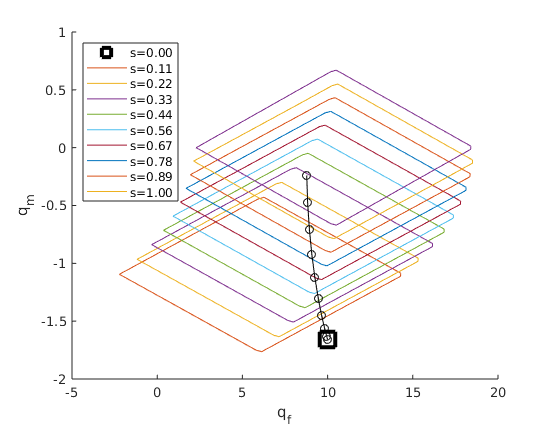

figure()
hold on
plot(q(1, 1), q(3, 1), "ksquare", "markersize", 15, "linewidth", 3);
xlabel("q_f")
ylabel("q_m")
plot(paths_qf', paths_qm')
plot(q(1, :), q(3, :), 'k-o');

legend("s=0", text_labels, "location", "northwest");
set(gcf, "visible", true)

tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

Q_tip = [0; 0; 0];
opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt");
f = @(mat_in) check_equilibrium(mat_in, Q_tip, p, struct_design);
[soln_fsolve, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


disp(res)

   1.0e-12 *

   -0.3197   -0.3197    0.1350   -0.3197   -0.3197    0.1350   -0.3197   -0.3197   -0.3197   -0.3197
   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0044   -0.0044    0.0027   -0.0044   -0.0044    0.0022   -0.0044   -0.0044   -0.0049   -0.0044



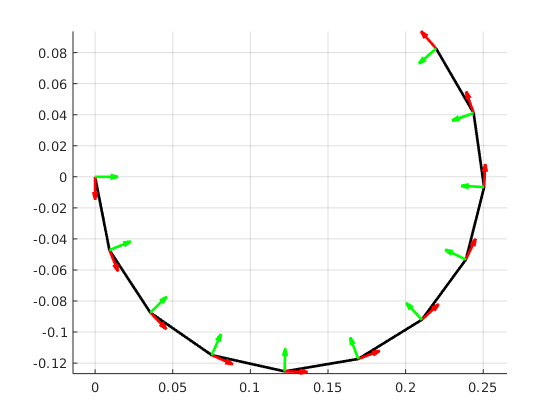

poses = calc_poses(g_0, soln_fsolve);
ax = axes(figure());
plot_poses(poses, ax);
grid on
set(gcf, "Visible", true)

toc

Elapsed time is 0.962697 seconds.


function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function ps = outline_pressure_space(max_ps, actuation_mode, N_edge)
    %%% Create a square path in pressure-space with N_edge points along each
    %%% edge using a corner definition: min_ps defines the bottom left
    %%% corner, and max_ps defines the top right corner. The path begins
    %%% and ends at the bottom left corner.
    %%%
    %%% Parameters:
    %%%  - max_ps: [60, 100, 100, 60] (kpa)
    %%%  - actuation_mode: [1 2 1 2]
    %%%  - N_edge: 50

    % Determine the phases of each trapezoid wave based on the actuation
    % modes. 
    % Currently mode-2 is defined starting a quarter period later than mode1
    phases = zeros(size(actuation_mode));
    for i = 1 : length(actuation_mode)
        mode_i = actuation_mode(i);
        
        if mode_i == 1
            phases(i) = 0;
        elseif mode_i == 2
            phases(i) = 1;
        end
    end
    
    t = linspace(0, 4, N_edge*4);
    ps = zeros(length(max_ps), length(t));
    for i = 1 : length(max_ps)
        ps(i, :) = max_ps(i) * trapezoid_wave(t - phases(i));
    end
end

function sig = trapezoid_wave(s)
    %%% Sample a trapzoid wave with period 1s at times s.
    %%% The trapezoid has amplitude 0.5 and is centered at 0.5
    %%% ie, it switches between 0 and 1.
    s = mod(s, 4);
    sig = zeros(size(s));
    for i = 1 : length(s)
        s_i = s(i);
        
        if s_i < 1
            sig(i) = 1 * (s_i);
        elseif (s_i >= 1) && (s_i < 2)
            sig(i) = 1;
        elseif (s_i >= 2) && (s_i < 3)
            sig(i) = -1 * (s_i - 2) + 1;
        else
            sig(i) = 0;
        end
    end
end